# HW 5 Part I:  Phase-Based Exoskeleton Control.

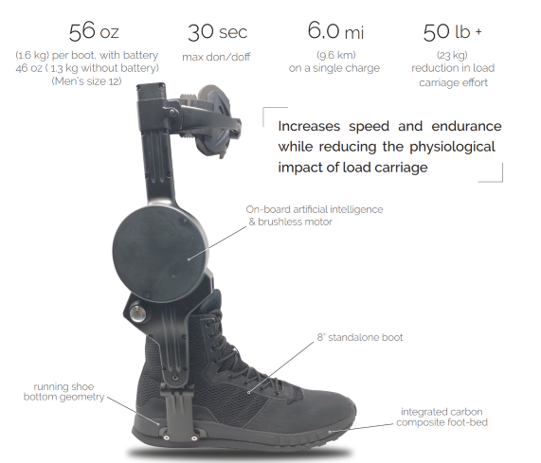

## 1.a. Load the data

In this homework, we will simulate a phase based controller for an ankle exoskeleton. The data is similar to HW 4: Positive moments and velocites at the ankle are in dorsiflexion. Note: I have also rotated the IMU on the right gastroc such that if the person is standing, positive x = right, positive y = forward (anterior), and positive z = upwards (superior), with the gyros following right hand rule.  Similarly to the previous homework, we will focus only on the right leg for simplicity.

clear; close all; clc
addpath('HW5_data\', 'HW5_functions\')
file2load  = "0deg_1.2ms_HW4.mat"; % Load the intermediate walking speed trial
load(file2load);
head(D) % Show the top 8 rows of the data table (D)

ans = 8×21 table
       Time            R_COP               L_COP                       R_F                             L_F                          R_Accel                          R_Gyro                            L_Accel                            L_Gyro                 R_Ankle_Angle    L_Ankle_Angle    R_Ankle_Velocity    L_Ankle_Velocity    R_Ankle_Moment    L_Ankle_Moment    R_Knee_Angle    L_Knee_Angle    R_Knee_Velocity    L_Knee_Velocity    R_Knee_Moment    L_Knee_Moment
    __________    ________________    ________________    _____________________________   

## 1.b Identify IMU signal that can be used for heel strike detection

In order to collect training data that doesn't require the treadmill, we will need to develop an IMU-based heel strike detector.  Use the original treadmill force-based heel strike detector (GetHeelStrikes) to plot the average and standard deviation segmented **sagittal plane** gyro vs gait phase (using SegmentDataByPhase).  The keys for these functions have been included.  This time, use the plotting funtion "*errorbar*," which will allow you to plot both the mean and std. [5]

*Hint: both "mean" and "std" have a default "axis" (rows vs columns) by which to take the mean / std, which does not work correctly with the matrix that "SegmentDataByPhase" returns.  Either transpose the matrix prior to taking the mean / std, or provide an optional argument to "mean" and "std" to operate along the other dimension. *

*Hint: To make sure you're on the right track--the plot should look like the following:*

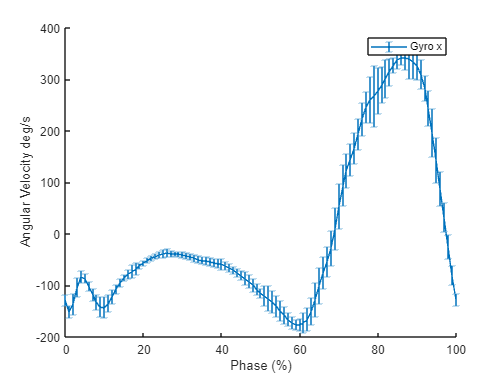

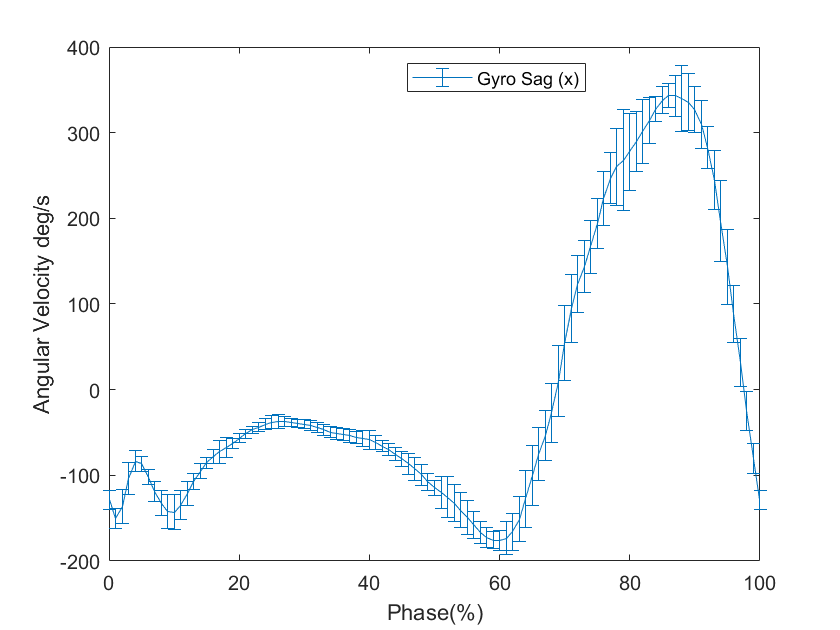

% Your code here
R_heel_strikes_from_force = GetHeelStrikesKey(D.R_F(:,3));
gyro_sag = SegmentDataByPhaseKey(R_heel_strikes_from_force, D.R_Gyro(:,1))';
m=mean(gyro_sag)';
s=std(gyro_sag)';
gait=0:1:100;

figure
errorbar(gait,m,s);
xlabel("Phase(%)");
ylabel("Angular Velocity deg/s");
legend('Gyro Sag (x)')


legend('Position',[0.4836,0.85476,0.21429,0.045238])

## 1.X IMU-based Heel Strike Detector

As seen above, the x axis of the gyro has a large peak around 90% of gait phase, or 10% before heel strike.  **Modify "DetectHeelStrikesIMU.m,**" which takes in the sagittal plane gyro signal, and returns a vector containing the heel strikes.  Your function will need to:

- Low pass filter the data (it will help tremendously to plot the filtered data against the unfiltered data to make sure you are filtering it appropriately to get rid of inadvertent peaks due to noise!!).  

- Find when both of the following conditions are met: a) a data point is a peak (above both its neighbors), and b) is above some minimum threshold (I recommend using 200 deg/s).  

- Adds a short delay to better correspond with the heelstrikes detected by the force plates (the exact value is up to you). 

Use your new function to find the "R_heel_strikes_from_IMU," and **show** (however you'd like!) that they align (approximately) with the heel strikes found from the treadmill's force sensors.  Again, I highly recommend plotting the filtered gyro data below to make sure it's smooth enough to show only one peak per stride. [15]

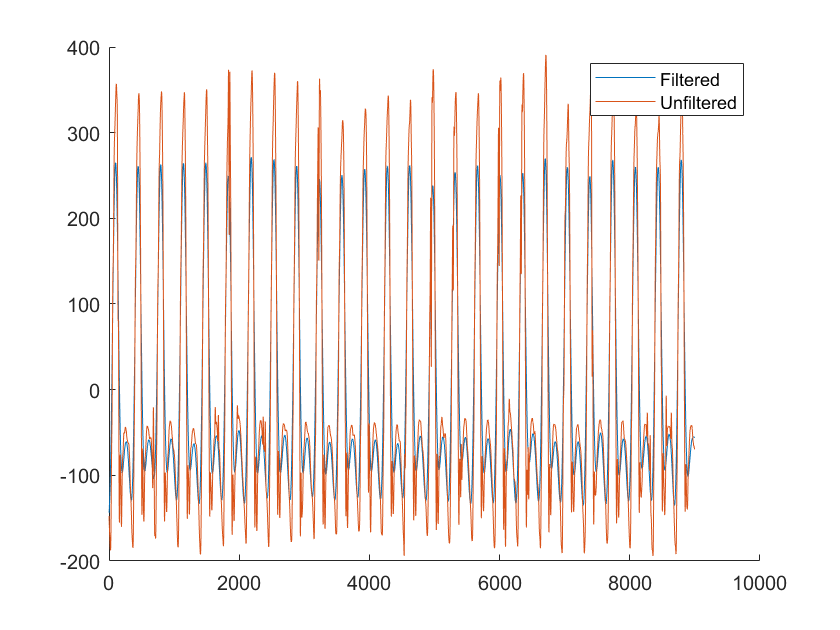

% your code here
R_heel_strikes_from_IMU = DetectHeelStrikesIMU(D.R_Gyro(:,1));

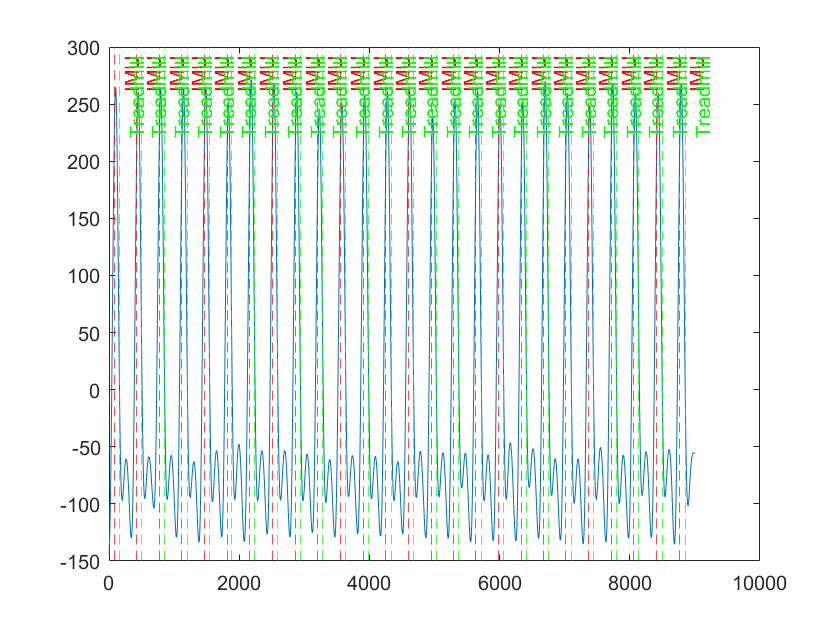

% figure 
hold on;
xline(R_heel_strikes_from_IMU,'--r','IMU');
xline(R_heel_strikes_from_force,'--g','Treadmill');
hold off;

% legend ('Filtered Gyro','HS from IMU','HS from Treadmill')
% plot(D.R_Gyro(:,1))
% xline(HS_detect,{'HS_byPhase'});
% plot(HS_detect);
% plot(HS_IMU);

## 2.a Gait Phase Label

**Modify GetGaitPhase.m,** so that it takes in the time vector and the heel strike indices and returns the gait phase.  Gait phase should be defined as 0 at heel strike and be approaching 100 at the next heel strike before being reset to 0. We can use "NaN" for all values before the first heel strike. Plot gait phase below (see image below for the target plot).   I've helped you get started by first iterating through the heel strikes to get a list (array) of the stride durations (difference in time between consecutive heel strikes).  Now, use a for loop to cycle through the whole time vector, keeping track of when the most recent heel strike was, and describing the time elapsed since the most recent heel strike as a fraction of the current stride duration. [15]

*Hint: as you loop through, you will need to recognize if the index corresponds with a heel strike index, so you can +1 to your stride_idx counter. *

*Note: If you get super stuck on this, a) you're always welcome at office hours, b) I have also included a vector ('r_gait_phase_key.mat') in the HW5_functions folder; you can load this vector and set D.R_Gait_Phase equal to it, and move forward.*

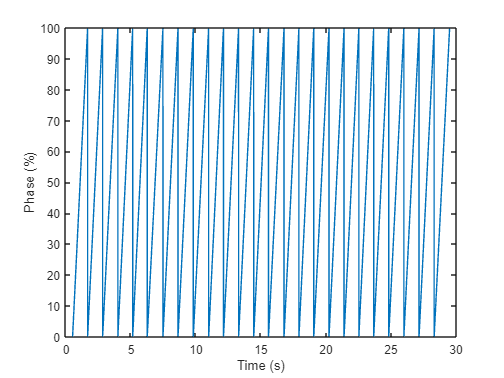

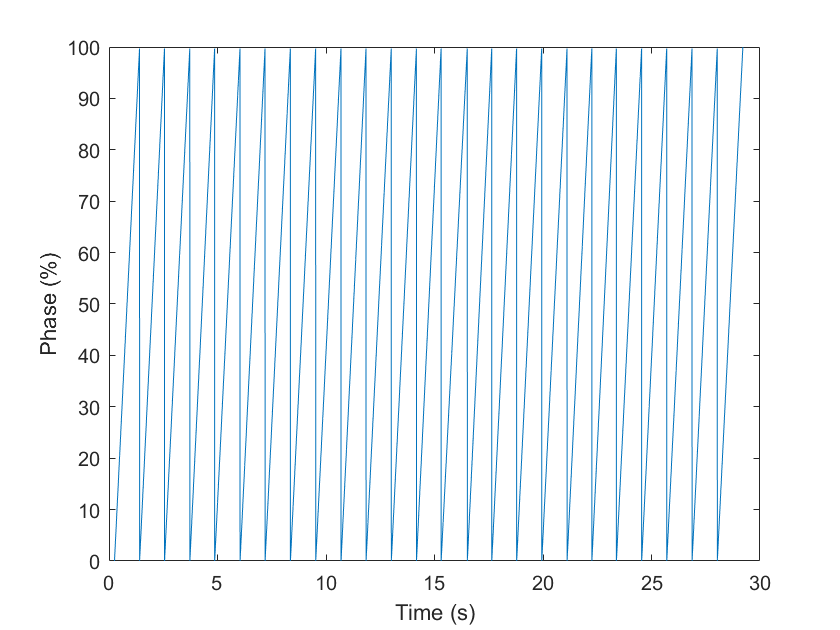

% Do not modify this code
D.R_Gait_Phase = GetGaitPhase(D.Time, R_heel_strikes_from_IMU);
figure;
plot(D.Time, D.R_Gait_Phase)
ylabel('Phase (%)')
xlabel('Time (s)')

## 3.a Gait phase regression using instantaneous values

The only way for us to label gait phase was in post-processing; we needed to know when the next heel strike would be.  We could not do this in real time, as our controller needs an instantaneous estimate of gait phase--meaning before the next heel strike has occurred!  The idea here is to use sensors (like the IMU) to *predict* gait phase, using only the current and past data, but no future data. That way, our gait phase estimator can be capable of being deployed in real time.

To start, we will use the instantaneous values of the following signals: (["R_Accel", "R_Gyro", "R_Ankle_Angle", "R_Ankle_Velocity"]) to predict R_Gait_Phase with a linear model.  Inspect the output of the "mdl," which is a LinearModel object containing the coefficients for each of our eight channels, the intercept, some statistics for each parameter, and some performance metrics such as R^2 and RMSE.  Nothing specific to do here, just read through the following code.

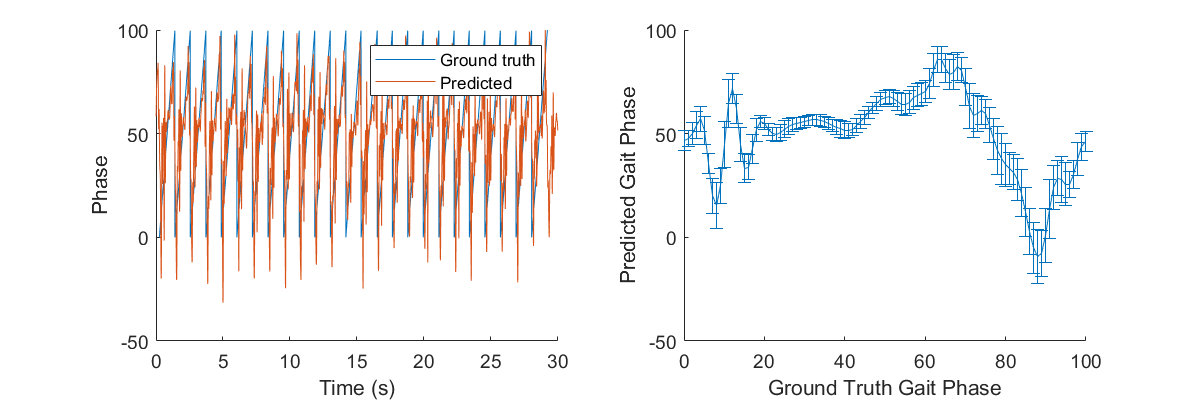

%Grab our signals, convert to matrix:
Sensors = table2array(D(:, ["R_Accel", "R_Gyro", "R_Ankle_Angle", "R_Ankle_Velocity"])); 
mdl = fitlm(Sensors, D.R_Gait_Phase);
predicted_phase = mdl.predict(Sensors);
fig3a = figure; hold on
subplot(1,2,1); hold on
plot(D.Time, D.R_Gait_Phase)
plot(D.Time, predicted_phase)
xlabel('Time (s)')
ylabel('Phase')
legend(["Ground truth", "Predicted"])

predicted_phases = SegmentDataByPhaseKey(R_heel_strikes_from_force, predicted_phase);
subplot(1,2,2); hold on
errorbar(0:1:100, mean(predicted_phases'), std(predicted_phases'))
fig3a.Position(3:4)=[1200,400];
xlabel("Ground Truth Gait Phase")
ylabel("Predicted Gait Phase")

## 3.b Feature Extraction

Looking at the RMSE, as well as the overall shape of the plot, I'd say our gait phase model using instantaneous values didn't do too well.  Let's add some new features of these signals (so called "**feature engineering"**) which will give the model some information about the sensor behaviors during a brief window of time preceding the instantaneous values.  **Modify "GetFeatures"** so that is takes in the window size to use, data table D, and the names of the channels to use, and returns a big matrix containing the 1) mean, 2) min, 3) max, and 4) instantaneous value of each feature. It's okay if it returns NaN for the first values, when there has not been enough data to apply our window. Your returned matrix should be 9001 x 32 (4 features x 8 channels). [10]

*Hint: You can iterate through table (and struct) fields using a string of the column name you'd like to acces, like so: D.(channels_to_use(1)) = ...*

*Note: Worst case, you can load the file "features_plus_noise_key.mat," to move on.  I've added a little noise to it to help with grading, so don't use it as a perfect guide! *

% Do not modify this code
channels_to_use = ["R_Accel", "R_Gyro", "R_Ankle_Angle", "R_Ankle_Velocity"];
window_size = 100;
Features = GetFeatures(window_size, D, channels_to_use);

## 3.c Fit linear model with features

Using this new feature matrix, try fitting a linear model to predict R_Gait_Phase. Note the improvement to the RMSE compared to that found in 3.a. Similar to above, use SegmentDataByHeelStrikes and the errorbar function to plot predicted gait phase as a function of true gait phase. [10]

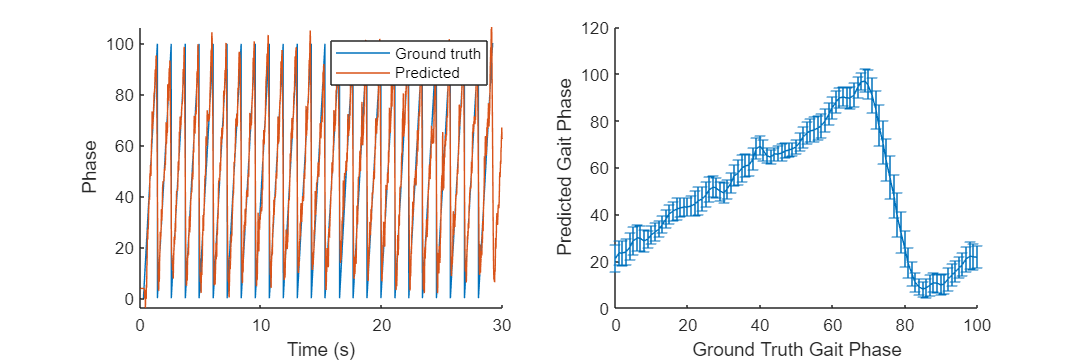

% Your code here
mdl_mod = fitlm(Features, D.R_Gait_Phase);
predicted_phase = mdl_mod.predict(Features);
fig3a = figure; hold on
subplot(1,2,1); hold on
plot(D.Time, D.R_Gait_Phase)
plot(D.Time, predicted_phase)
xlabel('Time (s)')
ylabel('Phase')
legend(["Ground truth", "Predicted"])

predicted_phases = SegmentDataByPhaseKey(R_heel_strikes_from_force, predicted_phase);
subplot(1,2,2); hold on
errorbar(0:1:100, mean(predicted_phases'), std(predicted_phases'))
fig3a.Position(3:4)=[1200,400];
xlabel("Ground Truth Gait Phase")
ylabel("Predicted Gait Phase")

## 3.c Mapping Phase to Exo Torque

Looking a little better, but still not great!  Let's go with it for now though.  How can we use gait phase to control the exoskeleton?  

Our goal is for the exoskeleton to approximately produce 25% of the bological ankle moment. Define a spline using Matlab's PCHIP function (https://www.mathworks.com/help/matlab/ref/pchip.html).  Use no more than six "spline points" to define this spline, with the x points ranging from 0 to 100. 

On the same plot, **plot the two following curves**:

- the average (with errorbars showing std) biological ankle moment (again, use "SegmentDataByPhase"), **multiplied by 0.25**

- Your PCHIP spline, assuming gait phase is perfect.

Here's my example, but you can probable define an even better spline!

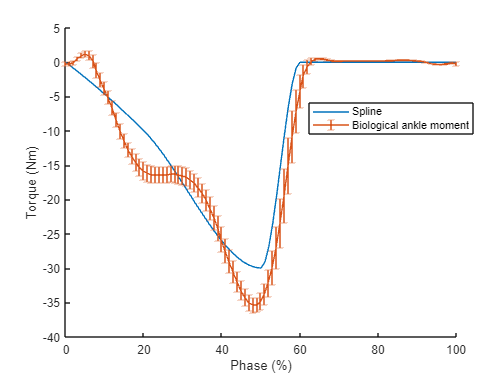

On another plot, **plot the two following curves****:**

- the average (with errorbars showing std) biological ankle moment (again, use "SegmentDataByPhase"), multiplied by 0.25

- the average (with errorbars showing std) exoskeleton torque, using your PCHIP spline

[10]

**Finally, Answer the question **below the code. 

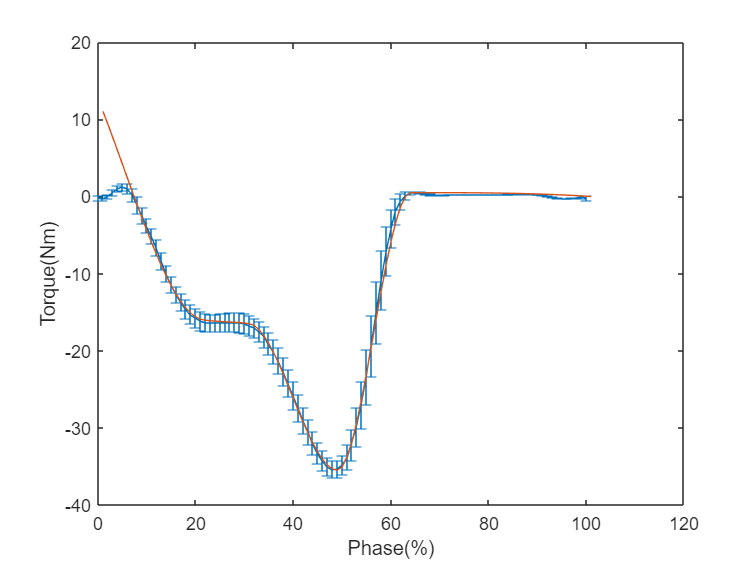

% Your code here
bio = 0.25*(SegmentDataByPhaseKey(R_heel_strikes_from_force, D.R_Ankle_Moment)');
m_b=mean(bio)';
s_b=std(bio)';

figure
errorbar(gait,m_b,s_b);
xlabel("Phase(%)");
ylabel("Torque(Nm)");
hold on;
spli_x = [7,20.5,30,48,63,100];
spli_y = [-1.09,-16,-16.5,-35.5,0.5,0];
xq = 0:1:100;
sp = pchip(spli_x,spli_y,xq);
plot(sp)
hold off;

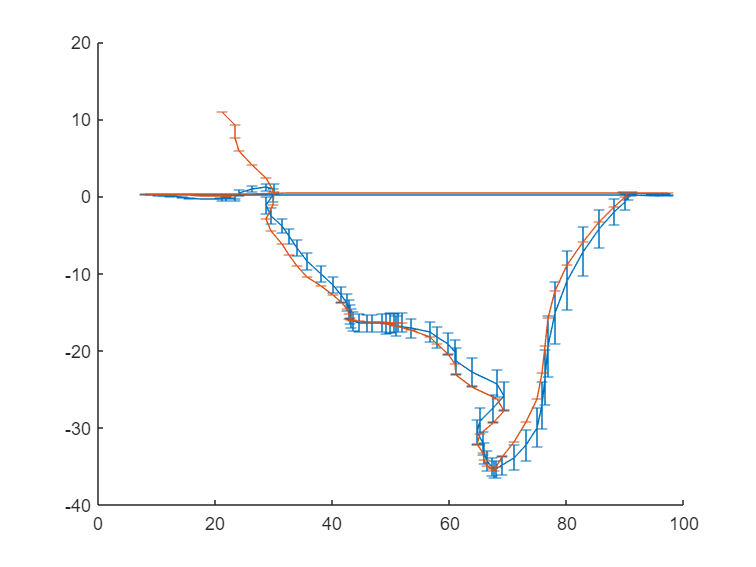

figure;
hold on;
errorbar(mean(predicted_phases,2),m_b,s_b);
m_sp = mean(sp',2);
s_sp = std(sp',0,2);
errorbar(mean(predicted_phases,2),m_sp,s_sp);

**Question**:

There seem to be large plantarflexion torque occuring around heel trike (95% - 100%, and 0% - 5%).  What is causing this? [5]

As the muscles are actually performing negative work by using eccentric force to lower the leg in swing, plantarflexion occurs between 95 and 100 percent of the gait cycle and is immediately followed by its 0 to 5 percent. The force of gravity is likewise acting downwards during the late swing phase, but because there is no muscle pulling up, plantarflexion occurs naturally. In order to initiate a good heel strike without any toe-ins or tip offs, a controller's holding torque should also be kept toward the dorsiflexion side.

## 4.a Phase: Solving the Discontinuity

One of the tricky issues with our naive approach to phase-based control is that we have a *discontinuity* at heel strike, where right before heel strike gait phase is approaching 100, but right at heel strike we jump down to 0.  Our regression is trying to learn that discontuity, but it can't do it perfectly, so it naturally passes through several intermediate values between 1 and 0.  Unfortunately, we map many of those intermediate values to a torque.  

To fix this issue, we can take advantage of a different way to describe phase--as a rotation.  Similarly, *theta* has a discontinuity between 0 and 2*pi, but we can represent theta (a single vector) in a different way without a discontinuity by taking the sin and cos of theta (two vectors), while assuming a radius of 1.  

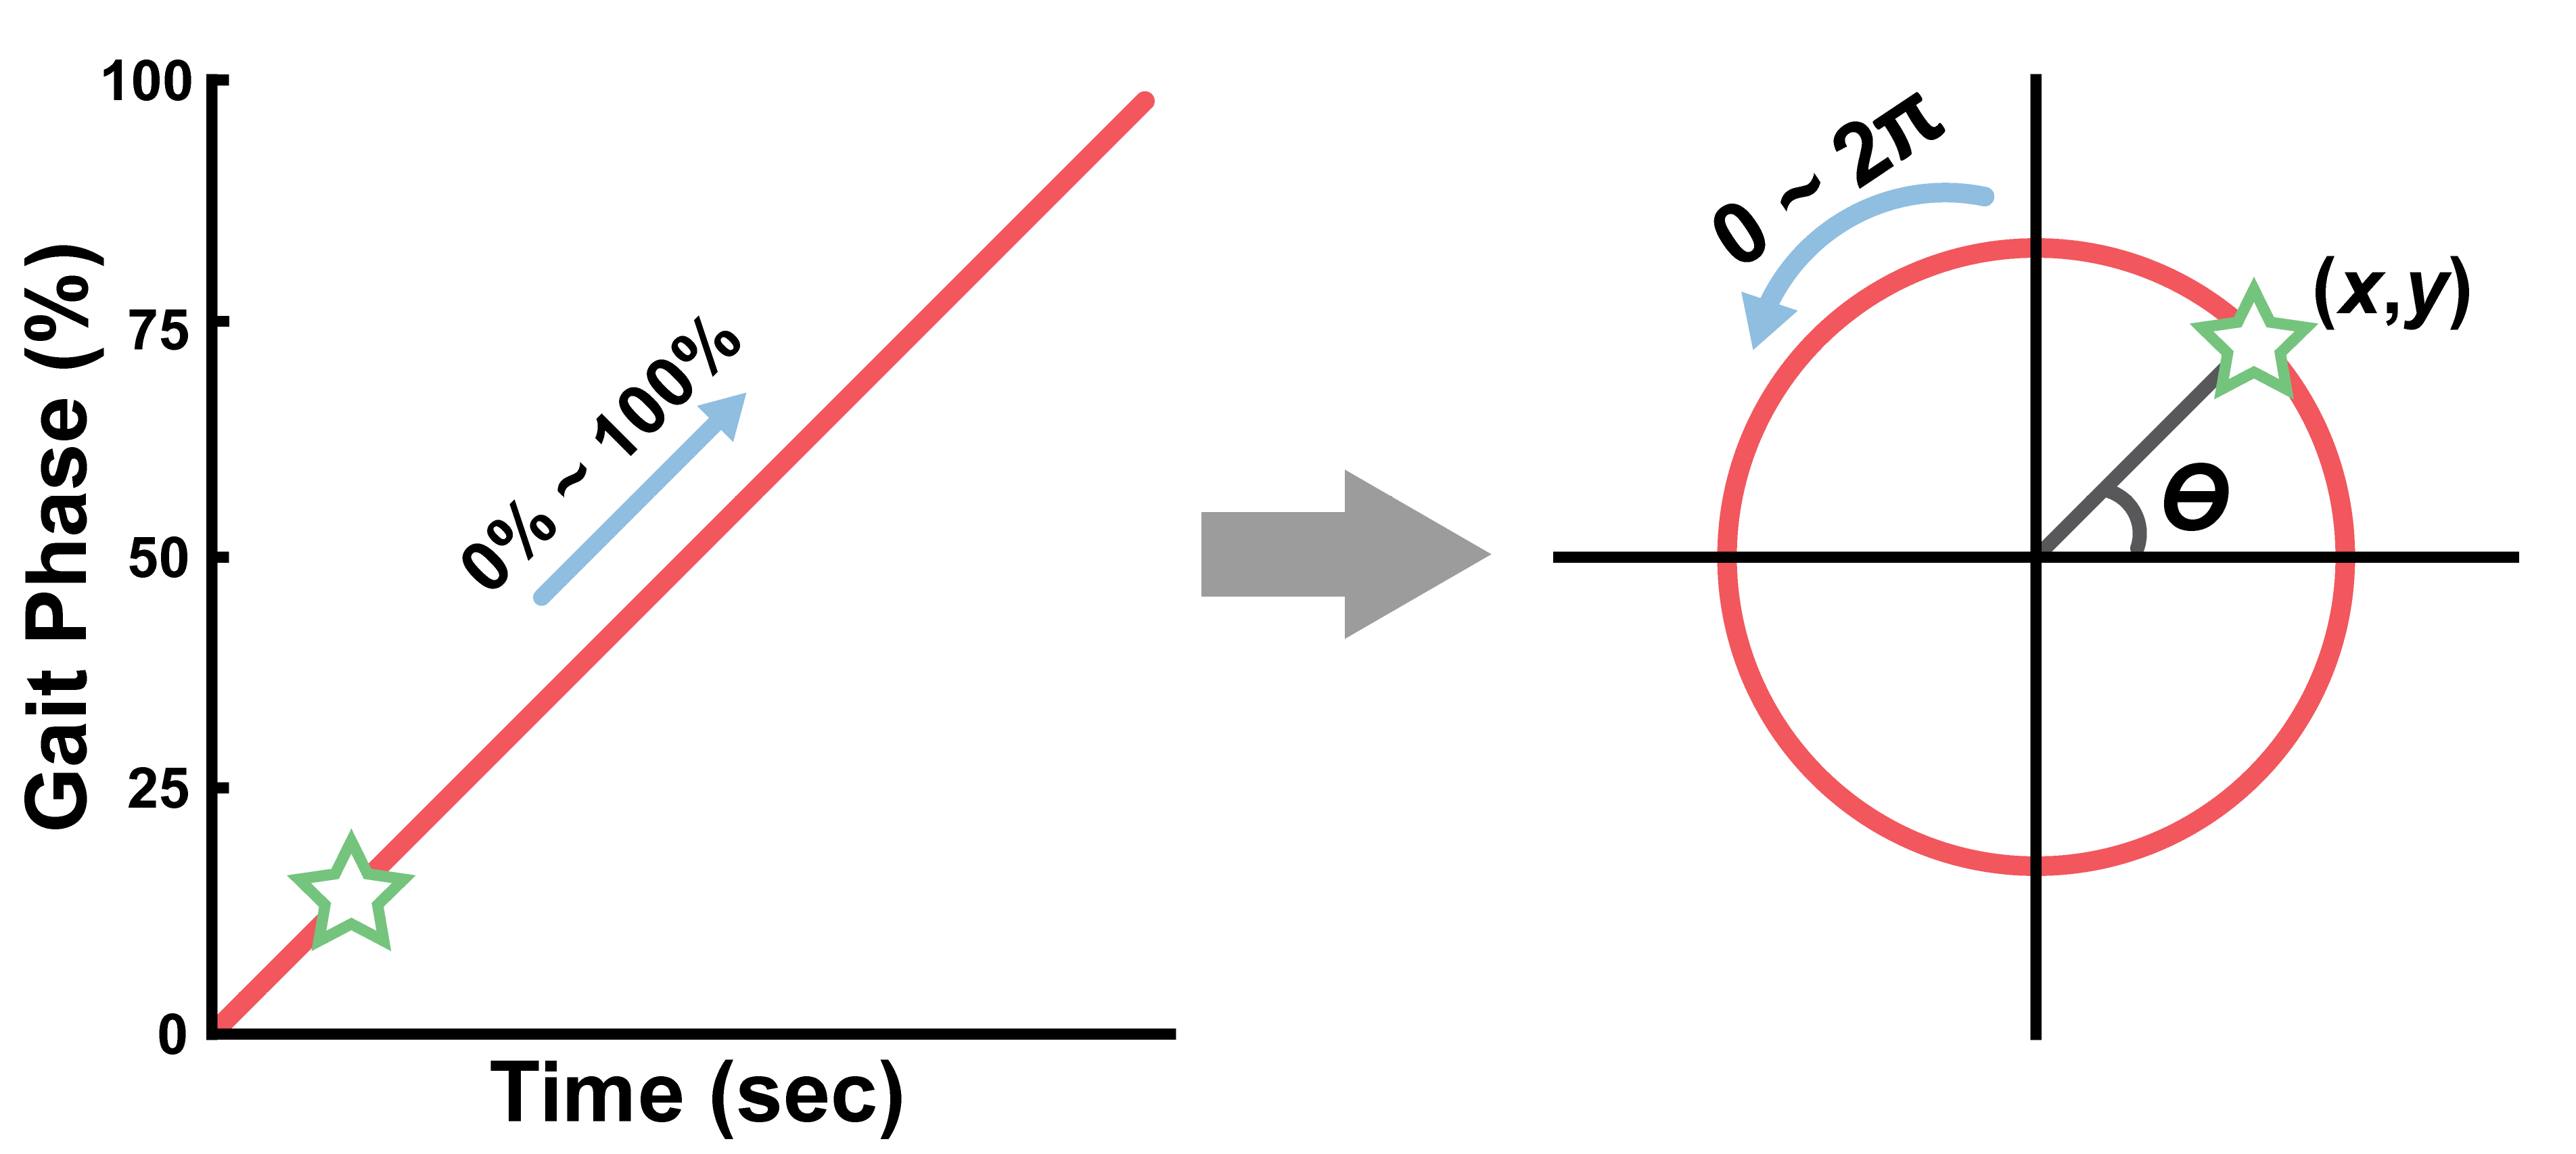

For more information on this approach, see: https://ieeexplore.ieee.org/ielaam/8253409/9007555/8941004-aam.pdf

**Write code **that treats D.R_Gait_Phase as a rotation between (0 and 2*pi) rather than a number between 0 and 100.  Split this "rotation" into two vectors--the cos and sin components.  Train two independent linear regressions to predict these components using the same feature matrix as the previous step.  Finally, combine the prediction of these regressions using atan2. 

**Show the following plots:**

- Predicted gait phase vs time and actual gait phase vs time (zoom in a little to show how well it did).

- A phase plot of predicted_phase_x vs predicted_phase_y (see below for the goal).

[15]

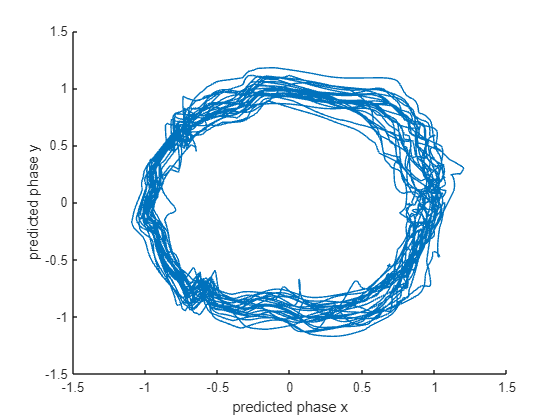

*Hint: There's a little deligence required in converting things to and from angles.  Unfortunately for our purposes, atan2 returns angles in the interval [-pi, pi] rather than [0 2pi].  The easiest option is probably to subtract pi from your angle, so that you are now mapping [0 100] to [-pi, pi].  Then train your linear models, and when you use atan2, you will just need to do the inverse map from [-pi pi] to [0 100].*

% Your code here
theta = ((D.R_Gait_Phase)*2*pi/100)-pi;

sin_gp = sin(theta);
cos_gp = cos(theta);

% figure;
% hold on;
% plot(sin_gp)
% plot(cos_gp)
sin_lin = fitlm(Features,sin_gp)

sin_lin = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8 + x9 + x10 + x11 + x12 + x13 + x14 + x15 + x16 + x17 + x18 + x19 + x20 + x21 + x22 + x23 + x24 + x25 + x26 + x27 + x28 + x29 + x30 + x31 + x32

Estimated Coefficients:
                    Estimate          SE         tStat       pValue   
                   ___________    __________    _______    ___________

    (Intercept)       -0.12503       0.01181    -10.586     4.9685e-26
    x1               -0.036858     0.0044724    -8.2412     1.9545e-16
    x2                   0.018     0.0022454     8.0162     1.2329e-15
    x3                -0.01766     0.0019088    -9.2523     2.7247e-20
    x4               -0.012835     0.0010158    -12.635     2.8145e-36
    x5         

cos_lin = fitlm(Features,cos_gp)

cos_lin = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8 + x9 + x10 + x11 + x12 + x13 + x14 + x15 + x16 + x17 + x18 + x19 + x20 + x21 + x22 + x23 + x24 + x25 + x26 + x27 + x28 + x29 + x30 + x31 + x32

Estimated Coefficients:
                    Estimate          SE         tStat        pValue   
                   ___________    __________    ________    ___________

    (Intercept)       -0.51785      0.021655     -23.914    1.9286e-122
    x1                 0.10589     0.0082004      12.913     8.5329e-38
    x2               -0.024265     0.0041171     -5.8938     3.9165e-09
    x3                 0.11486     0.0034998       32.82    9.0233e-223
    x4                0.011643     0.0018626      6.2508     4.2755e-10
    x5       

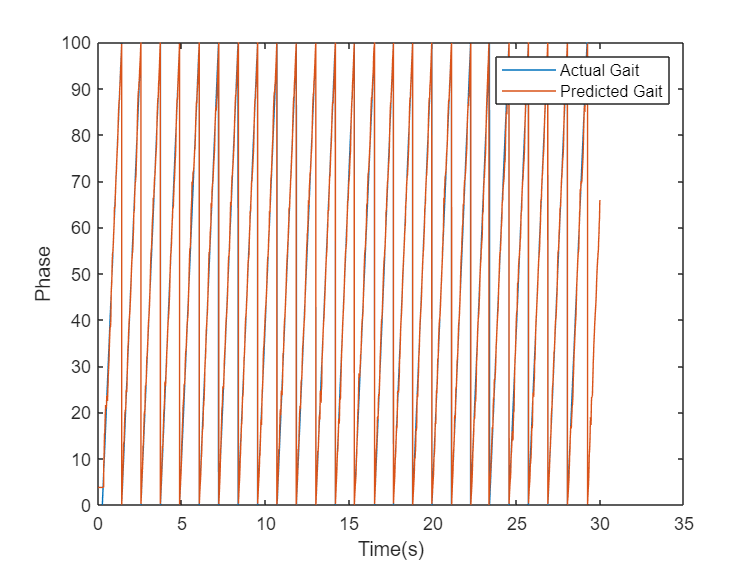

sin_pre=sin_lin.predict(Features);
cos_pre=cos_lin.predict(Features);

D.R_gait_cyclic=atan2(sin_gp,cos_gp);
theta_pre=atan2(sin_pre,cos_pre);
EMG_RMSE=5.87;
gait_pre=(theta_pre+pi)*100/(2*pi);
gait_seg=SegmentDataByPhaseKey(R_heel_strikes_from_force,gait_pre);
mean_gait = mean(gait_seg');

figure;
plot(D.Time,D.R_Gait_Phase);
hold on;
plot(D.Time,gait_pre);
legend('Actual Gait','Predicted Gait')
xlabel('Time(s)')
ylabel('Phase')
hold off

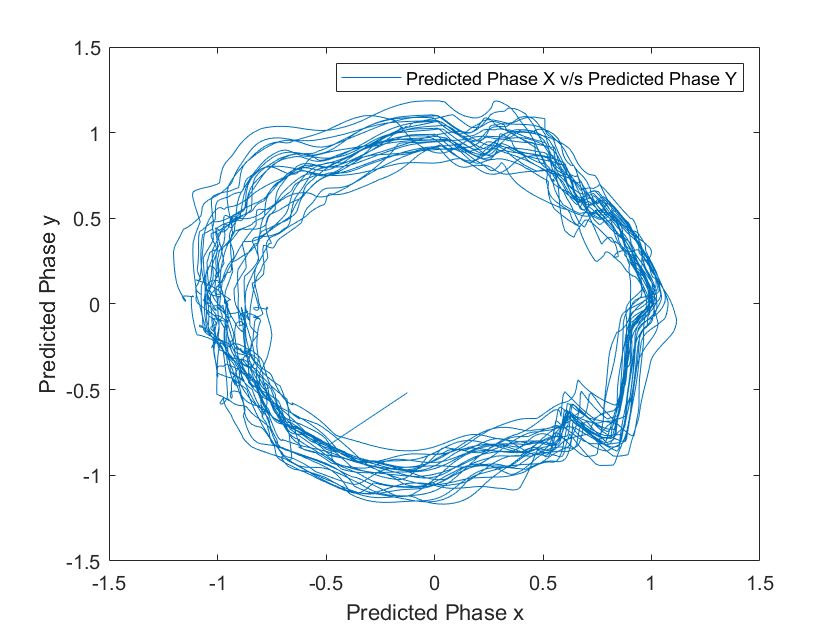


figure;
plot(sin_pre,cos_pre)
xlabel('Predicted Phase x')
ylabel('Predicted Phase y')
legend('Predicted Phase X v/s Predicted Phase Y')

## 4.b Torque vs Phase Revisited

Now that the phase prediction is much better, let's see how our exo torque looks.  Using the same type of PCHIP spline, plot the exo torque as a function of predicted gait phase, along with the target, which is 25% of the biological torque.  

Calculate the RMSE between our exo's torque and our target.  Feel free to modify your spline.  [5]

*How low can you get the RMSE?** Feel free to modify the spline points.  If you get RMSE below 2.2 Nm, +3 points. *

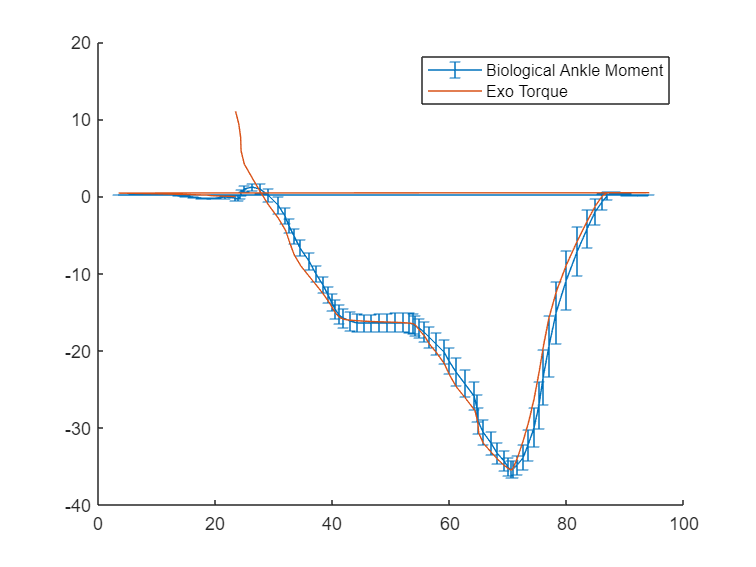

% Your code here
figure;
hold on;
errorbar(mean_gait,m_b,s_b);
plot(mean_gait,m_sp);
% x=[0,22,41,54,71,86];
% y=[0,0,-16,-16,-35,0];
% sp2 = pchip(x,y,xq);
% plot(sp2);
legend('Biological Ankle Moment','Exo Torque')
hold off;


% errorbar(predicted_phases,m_e,s_e);

%RMSE
err = m_b - m_sp;
RMSE = sqrt(mean(err.^2));
disp(mean(RMSE));

    2.1777



## 4.c Try our controller on slow walking

Load "0deg_0.9ms_HW4.mat" and try our new controller (which was only trained on the intermediate walking speed) on slow walking.  You'll be reusing the main lines of code from above, but I recommend appending "_slow" to your variable names so you don't get confused.  **Plot the following**:

-  Predicted gait phase vs time, and actual gait phase vs time. Zoom in a bit for clarity.  What's the RMSE?

-  25% of Biological torque vs time, and our exo torque vs time. 

Our simple linear model does pretty well! [10]

file2load  = "0deg_0.9ms_HW4.mat"; % Load the intermediate walking speed trial
temp_ = load(file2load);
D_slow = temp_.D;

%Your code here
head(D_slow)

ans = 8×21 table
       Time            R_COP               L_COP                       R_F                              L_F                          R_Accel                           R_Gyro                             L_Accel                           L_Gyro                R_Ankle_Angle    L_Ankle_Angle    R_Ankle_Velocity    L_Ankle_Velocity    R_Ankle_Moment    L_Ankle_Moment    R_Knee_Angle    L_Knee_Angle    R_Knee_Velocity    L_Knee_Velocity    R_Knee_Moment    L_Knee_Moment
    __________    ________________    ________________    _____________________________  

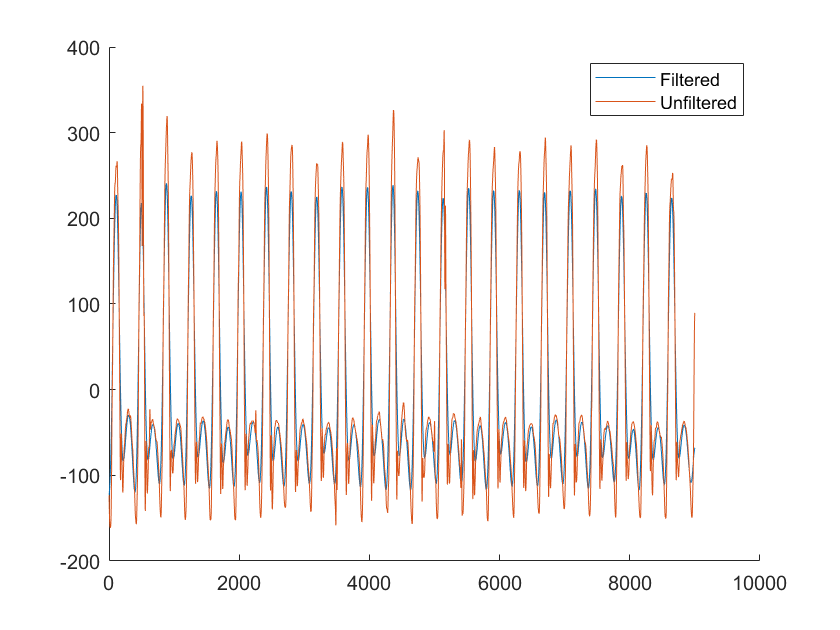



R_heel_strikes_from_IMU_slow = DetectHeelStrikesIMU(D_slow.R_Gyro(:,1));

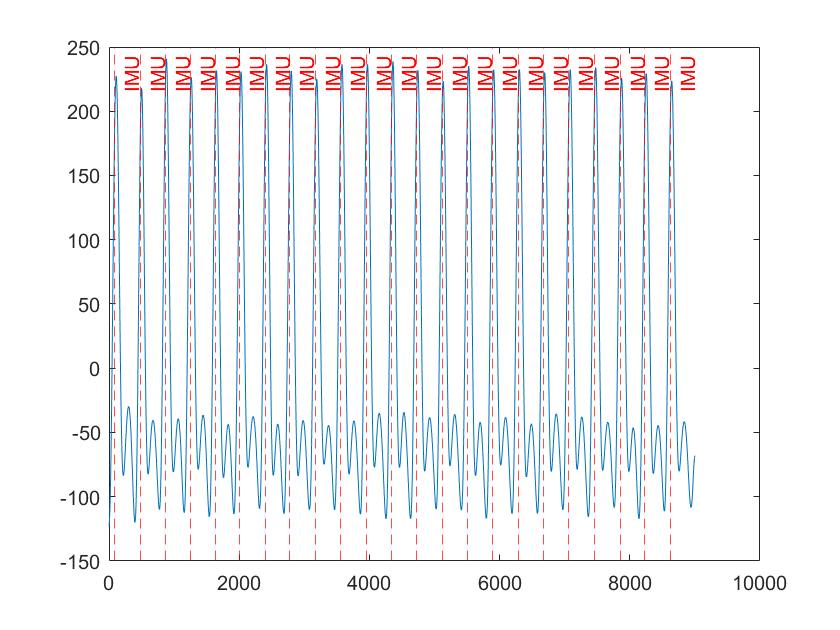

% figure 
hold on;
xline(R_heel_strikes_from_IMU_slow,'--r','IMU');
% xline(R_heel_strikes_from_force,'--g','Treadmill');
hold off;

D_slow.R_Gait_Phase = GetGaitPhase(D_slow.Time, R_heel_strikes_from_IMU_slow);

% From 4a
channels_to_use = ["R_Accel", "R_Gyro", "R_Ankle_Angle", "R_Ankle_Velocity"];
window_size = 100;
Features_slow = GetFeatures(window_size, D_slow, channels_to_use);

theta_slow=((D_slow.R_Gait_Phase)*2*pi/100)-pi;

sin_gp_slow=sin(theta_slow);
cos_gp_slow=cos(theta_slow);

sin_lin_slow=fitlm(Features_slow,sin_gp_slow)

sin_lin_slow = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8 + x9 + x10 + x11 + x12 + x13 + x14 + x15 + x16 + x17 + x18 + x19 + x20 + x21 + x22 + x23 + x24 + x25 + x26 + x27 + x28 + x29 + x30 + x31 + x32

Estimated Coefficients:
                    Estimate          SE         tStat        pValue   
                   ___________    __________    ________    ___________

    (Intercept)      -0.059762       0.02057     -2.9053      0.0036785
    x1                -0.13797     0.0053587     -25.747    7.7739e-141
    x2                0.016156     0.0030561      5.2866     1.2773e-07
    x3               -0.036686     0.0027029     -13.573     1.5644e-41
    x4              -0.0012915     0.0013046    -0.98996        0.32222
    x5  

cos_lin_slow=fitlm(Features_slow,cos_gp_slow)

cos_lin_slow = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8 + x9 + x10 + x11 + x12 + x13 + x14 + x15 + x16 + x17 + x18 + x19 + x20 + x21 + x22 + x23 + x24 + x25 + x26 + x27 + x28 + x29 + x30 + x31 + x32

Estimated Coefficients:
                    Estimate          SE         tStat        pValue   
                   ___________    __________    ________    ___________

    (Intercept)       -0.55939      0.028801     -19.422     2.9667e-82
    x1               -0.076119      0.007503     -10.145     4.7729e-24
    x2                0.017852     0.0042789       4.172     3.0498e-05
    x3                 0.17733     0.0037845      46.857              0
    x4               0.0095077     0.0018267      5.2049     1.9864e-07
    x5  

%Predictions
sin_pre_slow=sin_lin_slow.predict(Features_slow);
cos_pre_slow=cos_lin_slow.predict(Features_slow);

% D_slow.R_gait_cyclic=(atan2(sin_gp_slow,cos_gp_slow)+pi)*100/(2*pi);
D_slow.R_gait_cyclic=atan2(sin_gp_slow,cos_gp_slow)

D_slow = 9001×23 table
       Time            R_COP               L_COP                       R_F                              L_F                          R_Accel                           R_Gyro                              L_Accel                            L_Gyro                R_Ankle_Angle    L_Ankle_Angle    R_Ankle_Velocity    L_Ankle_Velocity    R_Ankle_Moment    L_Ankle_Moment    R_Knee_Angle    L_Knee_Angle    R_Knee_Velocity    L_Knee_Velocity    R_Knee_Moment    L_Knee_Moment    R_Gait_Phase    R_gait_cyclic
    __________    ________________    __

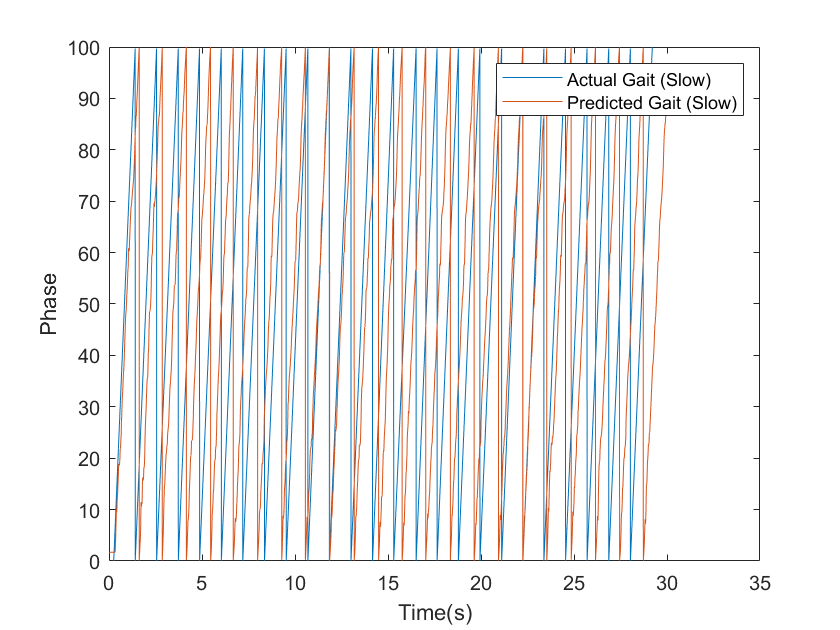

exo_slow_pred_cyc=(atan2(sin_pre_slow,cos_pre_slow)+pi)*100/(2*pi);

theta_pre_slow=atan2(sin_pre_slow,cos_pre_slow);
gait_pre_slow=(theta_pre_slow+pi)*100/(2*pi);
gait_seg_slow=SegmentDataByPhaseKey(R_heel_strikes_from_force,gait_pre_slow);
mean_gait_slow = mean(gait_seg_slow');

figure;
plot(D.Time,D.R_Gait_Phase);
hold on;
plot(D.Time,gait_pre_slow);
legend('Actual Gait (Slow)','Predicted Gait (Slow)')
xlabel('Time(s)')
ylabel('Phase')
hold off

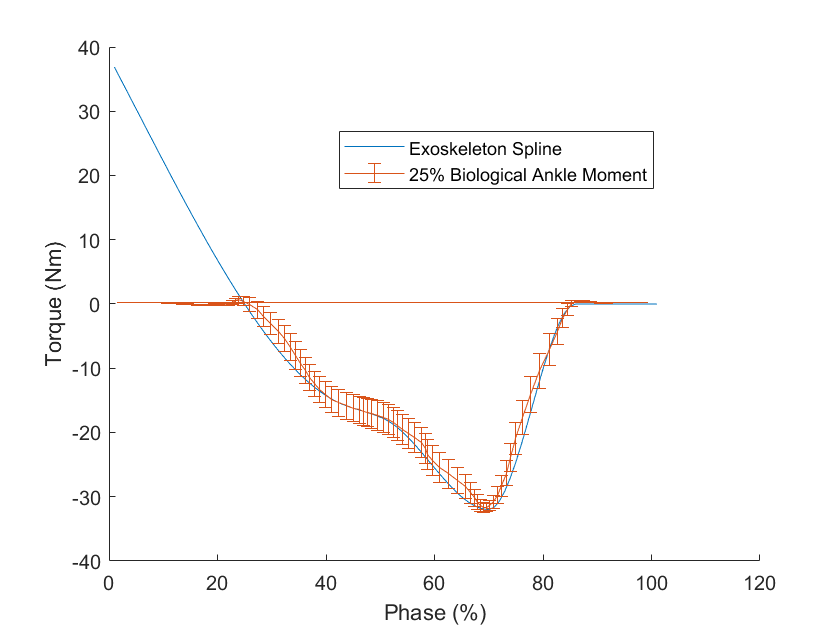

%Spline 
x_slow = [24,40.5,50,69,85,100];
y_slow = [0,-15,-18,-32,0,0];
xq2=0:1:100;
sp_slow=pchip(x_slow,y_slow,xq2);

%Ankle Torque
Mom_slow = 0.25*SegmentDataByPhaseKey(R_heel_strikes_from_IMU_slow,D_slow.R_Ankle_Moment);
Mom_slow=Mom_slow';
ankle_mom_slow= mean(Mom_slow);
ankle_std_slow = std(Mom_slow);

seg_slow_exo_pred_cyc=SegmentDataByPhaseKey(R_heel_strikes_from_IMU_slow,exo_slow_pred_cyc);
mean_slow_s_exo = mean(sp_slow',2);
std_slow_s_exo = std(sp_slow',0,2);
slow_mean_exo = mean(seg_slow_exo_pred_cyc');
%Figure Plotting 1
figure;
hold on;
plot(sp_slow);
errorbar(slow_mean_exo,ankle_mom_slow,ankle_std_slow);
xlabel('Phase (%)')
ylabel('Torque (Nm)')
legend('Exoskeleton Spline','25% Biological Ankle Moment')
legend("Position", [0.40347,0.7002,0.375,0.092619])
hold off;

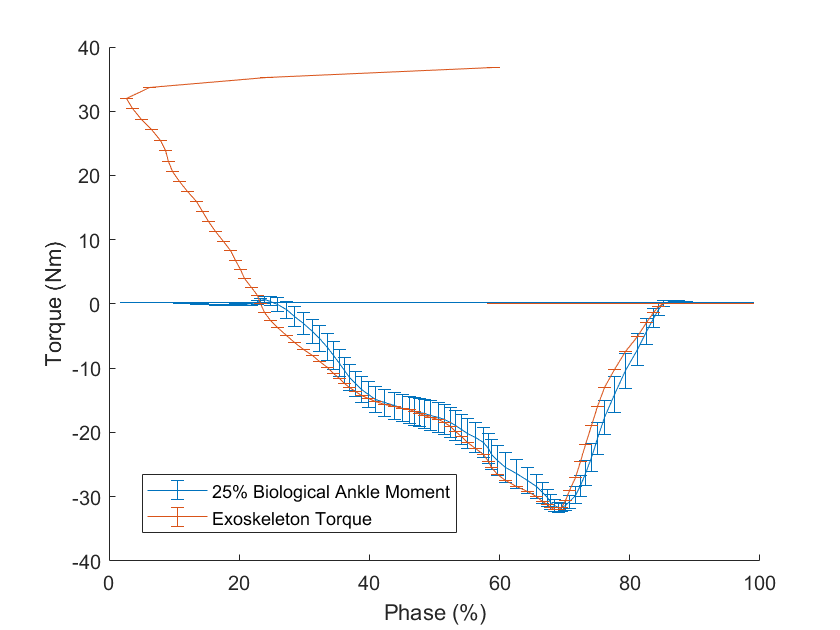

%Figure Plotting 2
figure;
hold on;
errorbar(slow_mean_exo,ankle_mom_slow,ankle_std_slow);
mean_slow_s_exo = mean(sp_slow',2);
std_slow_s_exo = std(sp_slow',0,2);

errorbar(slow_mean_exo,mean_slow_s_exo',std_slow_s_exo');
xlabel('Phase (%)')
ylabel('Torque (Nm)')
legend('25% Biological Ankle Moment','Exoskeleton Torque')
legend("Position", [0.16893,0.15436,0.375,0.092619])
hold off;

%RMSE for slow Walking
% rmse(ankle_mom_slow,mean_slow_s_exo','all')
err_slow = ankle_mom_slow - mean_slow_s_exo';
RMSE_slow = sqrt(mean(err_slow.^2));
disp(mean(RMSE_slow));

   10.5389



## 5.a Alternative Control: EMG 

We have also recorded EMG from the medial gastroc, which is one of the major plantaflexors.  This is sampled at a higher frequency, because there is important information contained above the nyquist freqeuncy for the markers and IMUs (300/2 = 150 Hz).

First, plot the raw_EMG (mV) on the same plot as ankle moment (Nm), to inspect if there is a general trend.  To do this, you will need to use the sampling frequency to create a new time vector for the EMG.  Zoom into the plot to show a couple strides. [5]

% load('raw_data\0deg_1.2ms_tracked.mat')
% % file2load_slow  = "0deg_1.2ms_HW4.mat"
% fs_EMG = round(qtm_0deg_1_2ms_tracked.Analog(2).Frequency);
% disp("fs_EMG: " + fs_EMG)

load('0deg_1.2ms_tracked.mat')
fs_EMG = round(qtm_0deg_1_2ms_tracked.Analog(2).Frequency);
R_EMG_gastroc = qtm_0deg_1_2ms_tracked.Analog(2).Data(1,:)';
disp("fs_EMG: " + fs_EMG)

fs_EMG: 4000


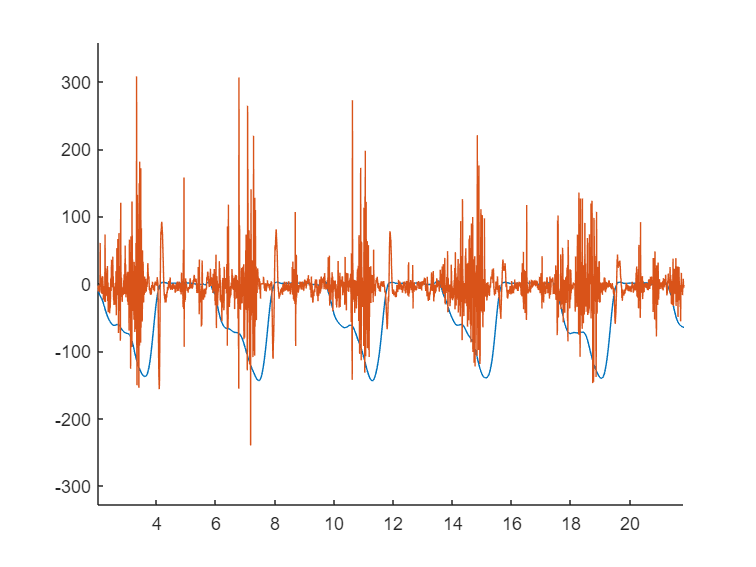

% EMG_seg = 
EMG_dur = linspace(0, 100, length(R_EMG_gastroc));
% EMG_seg = interp1(EMG_dur, gait)';

ankle_dur = linspace(0, 100, length(D.R_Ankle_Moment));
% EMG_seg = interp1(EMG_dur, gait)';

% Your code here
figure;
hold on;
plot(ankle_dur, D.R_Ankle_Moment);
plot(EMG_dur, R_EMG_gastroc);

xlim([2.0 21.8])
ylim([-328 359])

## 5.b Proportional Myoelectric Control

It seems like maybe there's a trend there, but we need to process the EMG to have a useable signal. Perform our sequence of EMG processing steps to get a general envelope: highpass filter with a 200 Hz filter to remove drift, rectify (take the absolute value), and then lowpass filter.  Pick a cutoff frequency for the lowpass filter that seems to do a good job of creating a profile that gives the EMG profile a similar profile to ankle torque.  Finally, downsample to 300 Hz, which we use for the rest of our data (I've included a helpful function "ResampleByFreq" to aid with this), and add a gain, such that this processed EMG signal closely matches with 25% of the biological ankle moment.  **Plot** EMG-based torque vs Time and 25% of ankle moment vs Time (and zoom in to a couple strides).** Calculate RMSE**. [15]

How low can you get the RMSE by modifying your filtering and gain value? +3 pts if you beat 6.0 Nm RMSE!

Finally, **Answers the questions below**:

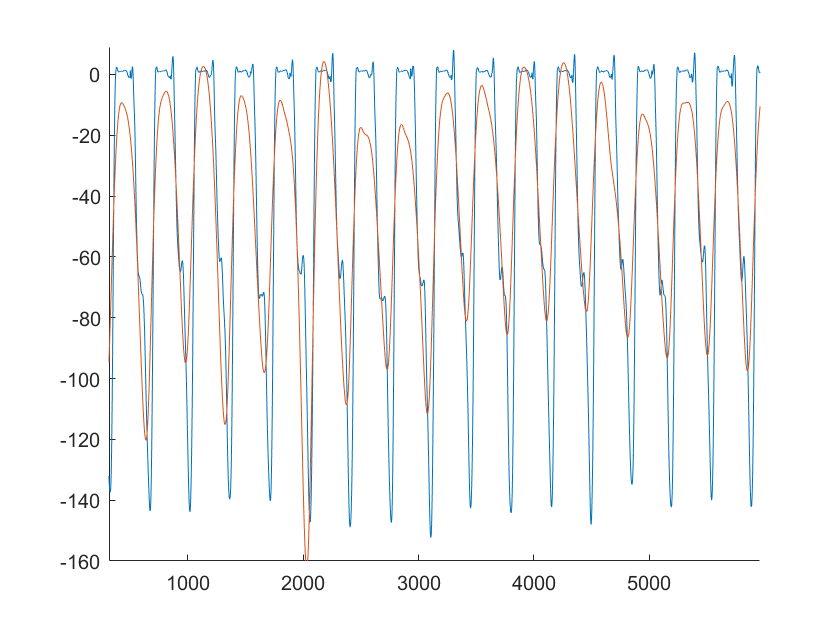

% Your code here
% R_EMG_gastroc
% EMG_seg = SegmentDataByPhaseKey(R_heel_strikes_from_force, EMG_down);
% EMG_mean = mean(EMG_seg);
[b,a] = butter(2,250/(12000/2),'high'); %2nd order, 200 Hz, high-pass
EMG_highpass = filtfilt(b,a, R_EMG_gastroc);
EMG_abs = abs(EMG_highpass);
[b,a] = butter(4,2/(12000/2),'low'); %2nd order, 200 Hz, high-pass
EMG_lowpass = filtfilt(b,a, EMG_abs); 
EMG_down = ResampleByFreq(EMG_lowpass, 4000, 300);
EMG_processed = -7*(EMG_down - EMG_down(1));
EMG_dur_down = linspace(0, 100, length(EMG_processed));
figure;
hold on;
plot(D.R_Ankle_Moment)
plot(EMG_processed)

xlim([315 5960])
ylim([-160 9])


%RMSE
EMG_err = D.R_Ankle_Moment - EMG_processed;
EMG__RMSE = sqrt(mean(EMG_err.^2));
disp(mean(EMG_RMSE));

    5.8700



**Questions**:

EMG control doesn't seem to be as easy to map to biological torque, at least with this analysis.  What are other factors or variables could we use to potentially improve our mapping between EMG and torque, and why? [5*]

<your answer here>

- We couls use the muscle activation patterns as their timings and activatioin can affect the resulting torque.

- Joint angles can also influence the torque generated by the muscles. Considering the angles can help to improve accuracy of mapping between EMG and torque.

- Another factor could be the power required by the muscles to perform an activity. This power can be caluclated from the EMG signal.

Compare and contrast the pros and cons of phase-based control and EMG control.  Which would you be more optimistic could be acceptable to users? Which would require more work to make it ready for users to take home? [5*]

<your answer here>

PHASE BASED CONTROLLER:

- Pros: It is easier to tune in based on individual requirements and their gait. USing MLE to predict the stance would help improve the accuracy of the system. 

- Cons: The data cllected should be accurate, otherwise the system would not work efficiently. Incorrect/noisy data may lead to errors. Any sudden movements would cause the system to fail.

EMG CONTROLLER:

- Pros: The data can be integrated easily for different gait patterns.

- Cons: It requires higher accuracy in setting up the system at the accurate location. Any changes in the placment would lead to errorneous results. As seen above, it is difficult to map EMG to torque. It needs to be combined with other variables to give a better result.

Some users may prefer the non-invasive nature of phase-based control, while others may prefer the greater control provided by EMG control. It may ultimately depend on individual preferences and the specific needs of the user.

In terms of work requirements to make it ready to take home, I feel the EMG would require more work to make it ready for users. It would require constant monitoring to ensure its location is accurate. A phase based controller would require lesser work.

## To turn in the homework:

Don't forget the paper analysis! This is in a separate Word Doc, and is a separate "Assignment" on canvas. 

Make sure all plots are visible (re-run your code if you have to, but don't forget to zoom into the figures if you need to). Save this matlab file as a pdf.  **Upload this pdf to the Assignment: "HW 5 Part I: Phase-Based Exoskeleton Control."**

Next, upload your Paper analysis to "HW 5 Part II: Paper Analysis"

Finally, upload a zip folder containing your Matlab scripts (will help us debug if there were issues) to "HW 5 upload Matlab Files here"